## Speech denoising by sparse coding

IFToolbox can be downloaded from teh codeocean [https://codeocean.com/capsule/1906064/tree/v1](https://codeocean.com/capsule/1906064/tree/v1)

% Fix seed
rng(7);
addpath(genpath('../../../IFToolbox'))

% Parametr
std_n = 0.3;
winlen = 256;
shift = winlen/4;

% Set STFT and iSTFT
[win, ~] = generalizedCosWin(winlen, 'hann');
win = calcCanonicalTightWindow(win, shift);
win = win/norm(win)*sqrt(shift/winlen);  % operator norm -> 1
STFT = @(X) DGT(X, win, shift);
iSTFT = @(X) invDGT(X, win, shift, winlen)*winlen;

% Load signal
eval('load mtlb, s = mtlb; clear mtlb')
s = zeroPaddingForDGT(s, shift, winlen);

% Make noise
n = std_n*randn(length(s), 1);

% Calculate observed signal
v = s+n;

% Check property of STFT
cv = STFT(v);
v_ = iSTFT(cv);
disp(['Reconstruction error: ', num2str(max(abs(v-v_)/max(v)))])

Reconstruction error: 4.0302e-16


% Initialize variable
uinit = cv;
u = uinit;
lm = 0.3;
stepsize = 0.1;
maxiter = 500;
snrs = nan(maxiter,1);
costs = nan(maxiter,1);

% Set cost function
cost = @(u) 1/2*norm(iSTFT(u)-v)^2+lm*sum(sum(abs(u)));

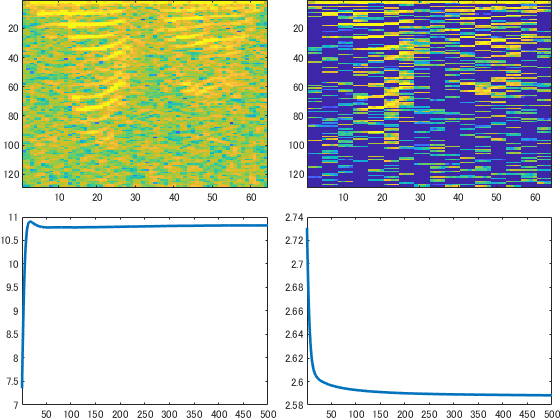

% Final visualization
fig = figure;
t = tiledlayout(2, 2,'TileSpacing','compact','padding','none');
nexttile(1)
oriplot = imagesc(20*log10(abs(cv)));
caxis([-60, 0]);

nexttile(2)
specplot = imagesc(20*log10(abs(u)));
caxis([-60, 0]);


nexttile(3)
snrplot = plot(snrs, 'LineWidth',2);
xlim([1, maxiter])


nexttile(4)
cplot = plot(costs, 'LineWidth',2);
xlim([1, maxiter])

% Main loop of ISTA
for m = 1:maxiter
    
    % Update u
    u = proxl21(u-stepsize*(STFT(iSTFT(u))-STFT(v)), lm*stepsize);
    
    % Visualization
    snrs(m) = snr(s, s-iSTFT(u));
    costs(m) = log10(cost(u));
    specplot.CData = 20*log10(abs(u));
    snrplot.YData = snrs;
    cplot.YData = costs;
    drawnow limitrate
    pause(0.1)
    
end

function y = proxl21(x, gam)
    [f,t] = size(x);
    x = reshape(x', [4, f*t/4]);
    l2 = sqrt(sum(abs(x).^2, 1));
    ratio = max(1-(gam./l2), 0);
    y = ratio.*x;
    y = reshape(y, [t, f])';
end